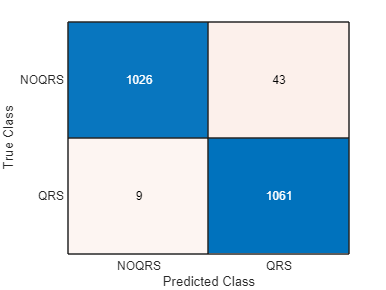

% VALIDATION SET
[YValid,scores_valid] = classify(TRAINED,validation_set,"ExecutionEnvironment","cpu");
confusionchart(validation_set.Labels,YValid)

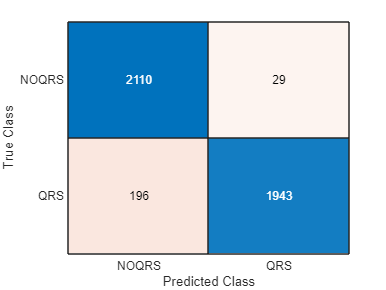

% TEST SET
[YPred,scores] = classify(TRAINED,test_set,"ExecutionEnvironment","cpu");
confusionchart(test_set.Labels,YPred)


X= predict(TRAINED,test_set,"ExecutionEnvironment","cpu");
Y = predict(TRAINED,validation_set,"ExecutionEnvironment","cpu");

%confusionchart(test_set.Labels,YPred)
rocObj = rocmetrics(validation_set.Labels,Y,["NOQRS","QRS"]);
rocObj.AUC

ans = 1×2 single row vector
    0.9962    0.9962


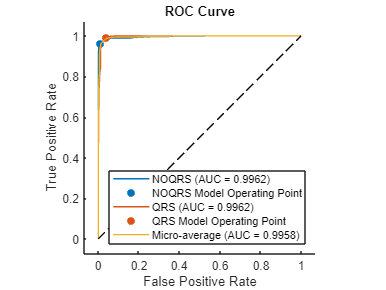

plot(rocObj,AverageROCType="micro")




rocObj = rocmetrics(test_set.Labels,X,["NOQRS","QRS"]);
rocObj.AUC

ans = 1×2 single row vector
    0.9941    0.9941


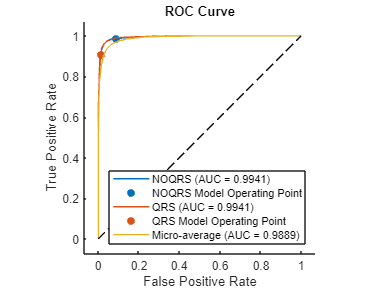

plot(rocObj,AverageROCType="micro")

% TEST SET
[YPred,scores] = classify(TRAINED,test_set,"ExecutionEnvironment","cpu");

Error using SeriesNetwork/predict
Too many output arguments.

confusionchart(test_set.Labels,YPred)